# Lab work C

clear all;
close all;

lab_work_C_init_routine;

lab_work_C_preparing_the_model;

V2cm_mf = function_handle with value:
    @(x2)x2.*7.456422751238219e-1-1.648066384406454


## Feedback linearization

k_mf = function_handle with value:
    @(r,x1,x2)sqrt(x1.*1.962e+3+6.2784e+3).*(r.*(3.0./8.0e+2)-x2.*2.796158531714332e-3+1.0./sqrt(x2.*1.962e+3+6.2784e+3).*(sqrt(x1.*1.962e+3+6.2784e+3).*5.151515151515152e-3-sqrt(x2.*1.962e+3+6.2784e+3).*5.151515151515152e-3).*3.768204915830296-sqrt(x1.*1.962e+3+6.2784e+3).*4.801484347388247e-4+sqrt(x2.*1.962e+3+6.2784e+3).*4.801484347388247e-4+2.559221365943785e-2).*8.757485523509194


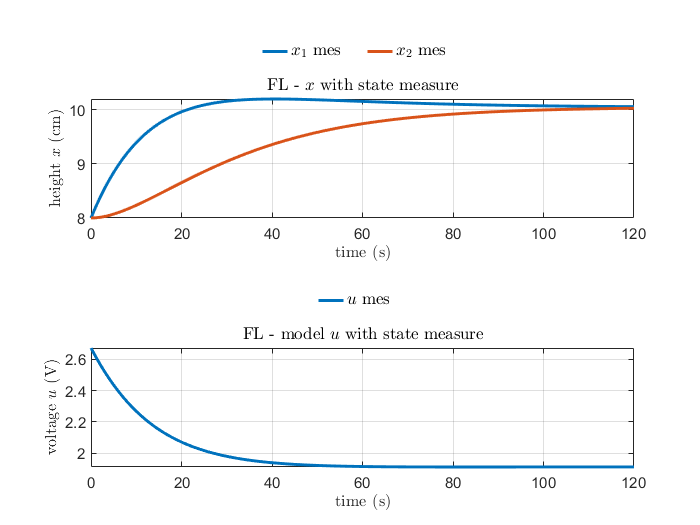

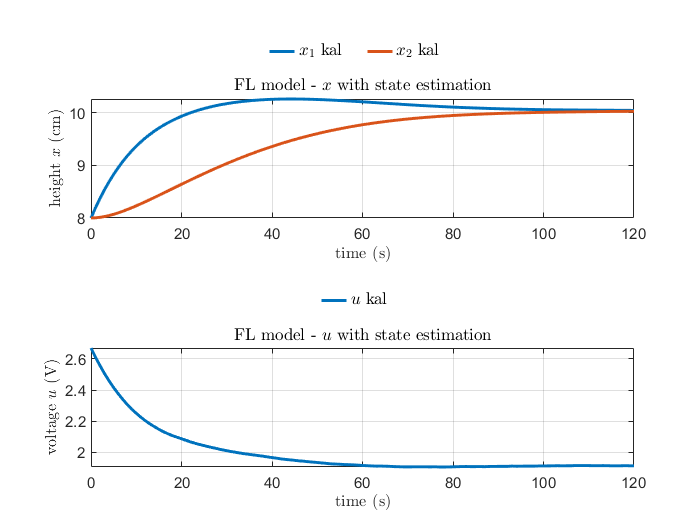

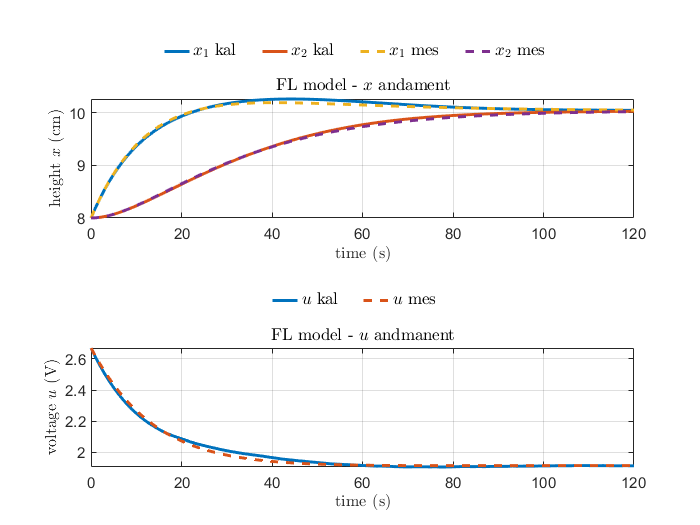

lab_work_C_feedback_linearization;

## Sliding control

u = function_handle with value:
    @(epsi,mu,p1,p2,r,x1,x2)((p2.*(sqrt(x1.*5.0+1.6e+1).*7.609042393596842e-2-sqrt(x2.*5.0+1.6e+1).*7.609042393596842e-2).*1.0./sqrt(abs(p1).^2+abs(p2).^2)+p1.*1.0./sqrt(x1.*5.0+1.6e+1).*1.0./sqrt(x2.*5.0+1.6e+1).*(x1.*2.7795e+4+8.8944e+4).*1.0./sqrt(abs(p1).^2+abs(p2).^2).*3.491988616282361e-6).*sqrt(x1.*5.0+1.6e+1).*sqrt(abs(p1).^2+abs(p2).^2).*(-1.734778086018821e+2))./p1-(mu.*sqrt(x1.*5.0+1.6e+1).*sqrt(abs(p1).^2+abs(p2).^2).*min([1.0,max([-1.0,(p1.*(sqrt(x1.*1.962e+3+6.2784e+3).*3.841187477910597e-3-sqrt(x2.*1.962e+3+6.2784e+3).*3.841187477910597e-3)-p2.*(r-x2.*7.456422751238219e-1+1.648066384406454))./epsi],[],2,'omitnan')],[],2,'omitnan').*1.734778086018821e+2)./p1


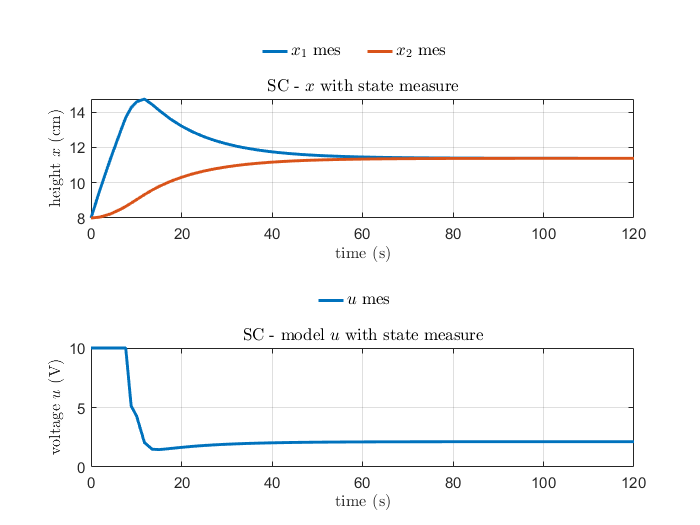

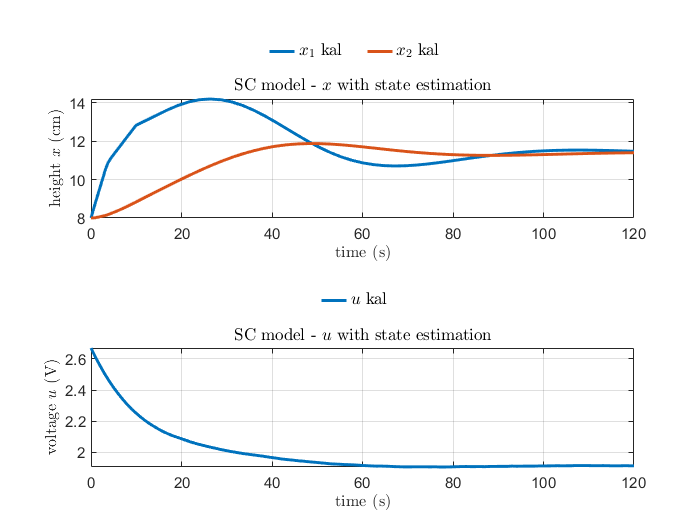

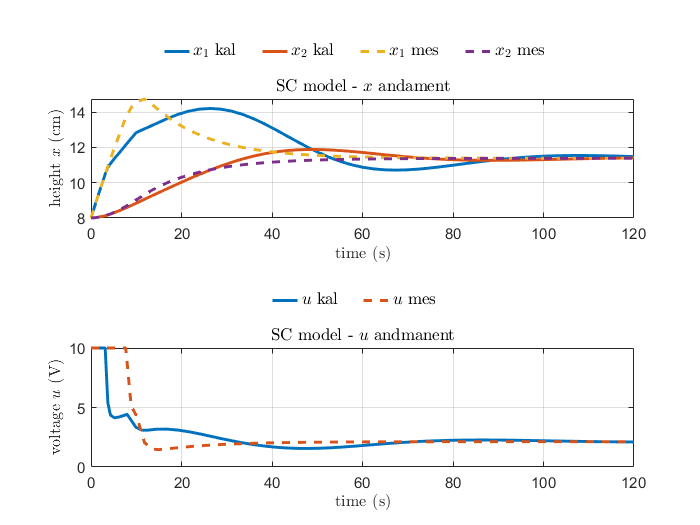

lab_work_C_sliding_mode;